# MATLAB Assignment 3 Phase 2: Further Exploring Bloom

Authors: S Hassan Shaikh, Jordan Chung-Lee, Gabriel Garcia

I will be further exploring the results of the Bloom prompt for both ChatGPT and Gemini. The target effect of bloom is to have it so that bright objects seem to be visibly brighter or glowing. In this project I will be comparing the 2 prompts in detail, observing their strengths and weaknesses, and I will also test the effect of combining them.

## Test 1: Lanterns

This is the test seen in the initial report, the conclusion I came up with is that with ChatGPT works well but has an issue where the image in general darkens or gets blurrier while Gemini produced better looking results. The 2 results are very different from one another and it seems they handled the tasks of creating a bloom effect very differently.

### Lanterns with ChatGPT's Bloom

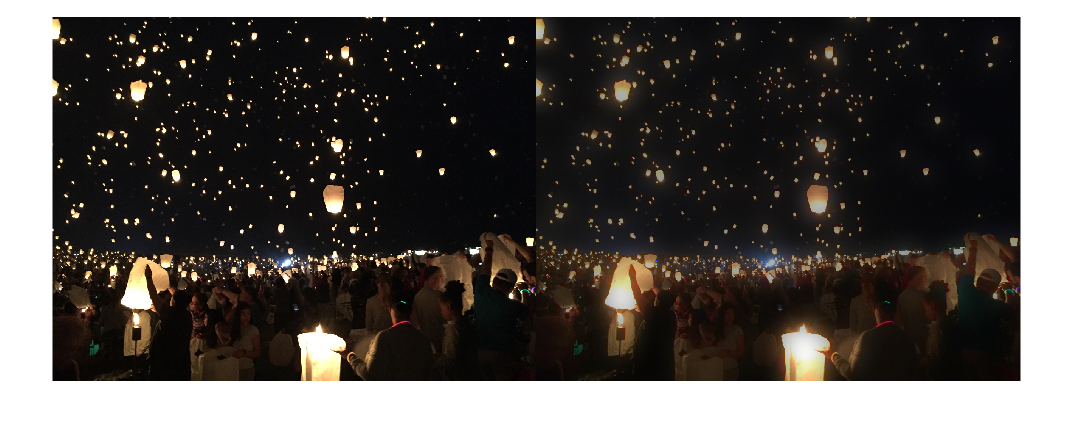

LanternsInput = imread("FlyingLanterns.jpg");
LanternsGPTBloom = addBloomEffect(LanternsInput,0.5,30);
LanternsGeminiBloom = addBloom(LanternsInput,0.4,50);
imshowpair(LanternsInput,LanternsGPTBloom,"montage")

### Lanterns with Gemini's Bloom:

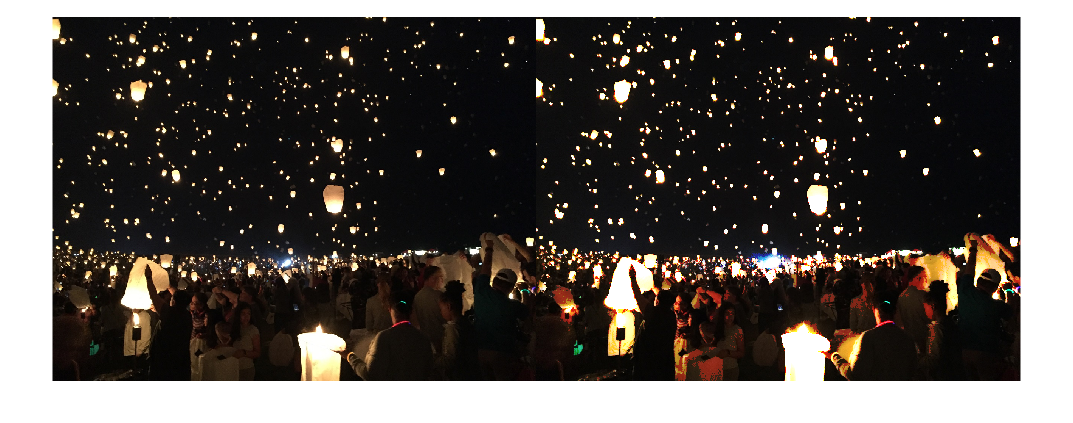

imshowpair(LanternsInput,LanternsGeminiBloom,"montage")

## Test 2: Street 1

This test uses an image built into MATLAB, namely "street1.jpg". Using this image the problems with both AI's implementations become apparent. ChatGPT's bloom seems to apply a general gaussian blur over the whole image and in some dark areas, such as the shadow under cars, there are visible blue sploches. Gemini's  bloom seems to produce patchy results where the pixels that meet or exceed the threshold seem to be harshly brightened while the other pixels remain relatively unchanged. In the latern images in test 1 this looked like good results which is while my remarks in "A3 Registry" were rather positive for Gemini.

### Street 1 with ChatGPT's Bloom

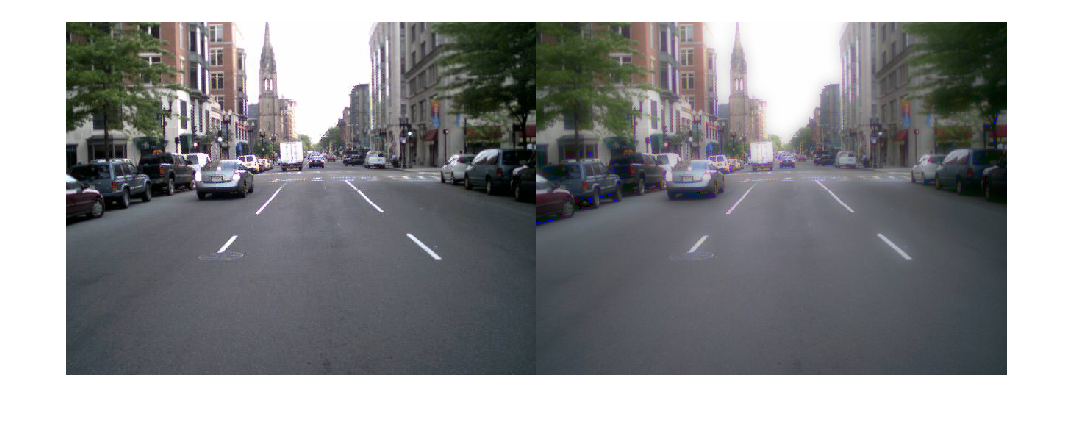

Streets1Input = imread("street1.jpg");
Streets1GPTBloom = addBloomEffect(Streets1Input,0.5,10);
Streets1GeminiBloom = addBloom(Streets1Input,0.4,150);
imshowpair(Streets1Input,Streets1GPTBloom,"montage")

### Street 1 with Gemini's Bloom

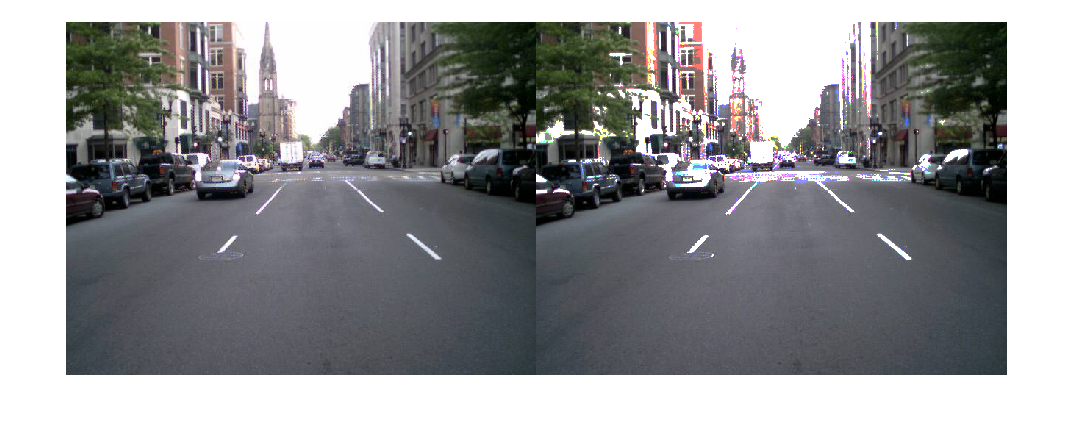

imshowpair(Streets1Input,Streets1GeminiBloom,"montage")

## Test 3: Street 2

This test uses an image built into MATLAB, namely "street2.jpg". The weird colors that show up in ChatGPT's bloom are still visible and the patchiness seen in Gemini's bloom become more apparent. 

### Street 2 with ChatGPT's Bloom

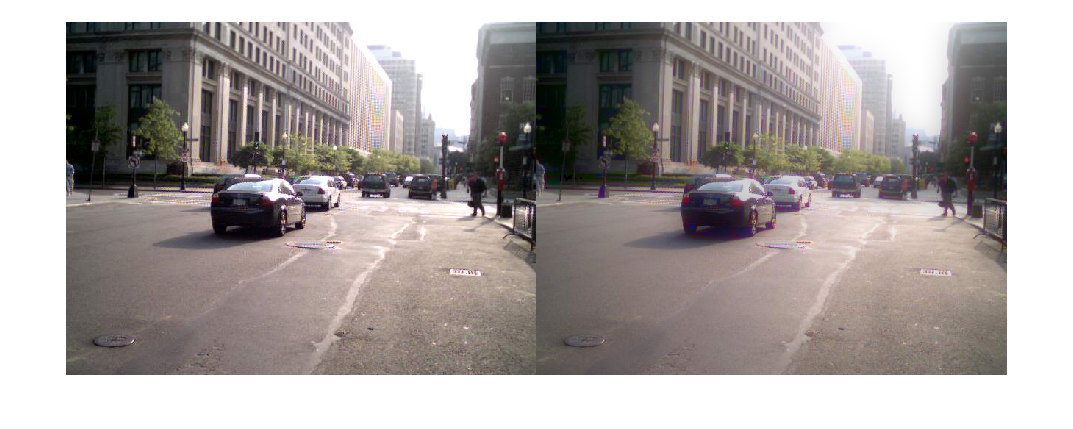

Streets2Input = imread("street2.jpg");
Streets2GPTBloom = addBloomEffect(Streets2Input,0.4,20);
Streets2GeminiBloom = addBloom(Streets2Input,0.4,180);
imshowpair(Streets2Input,Streets2GPTBloom,"montage")

### Street 2 with Gemini's Bloom

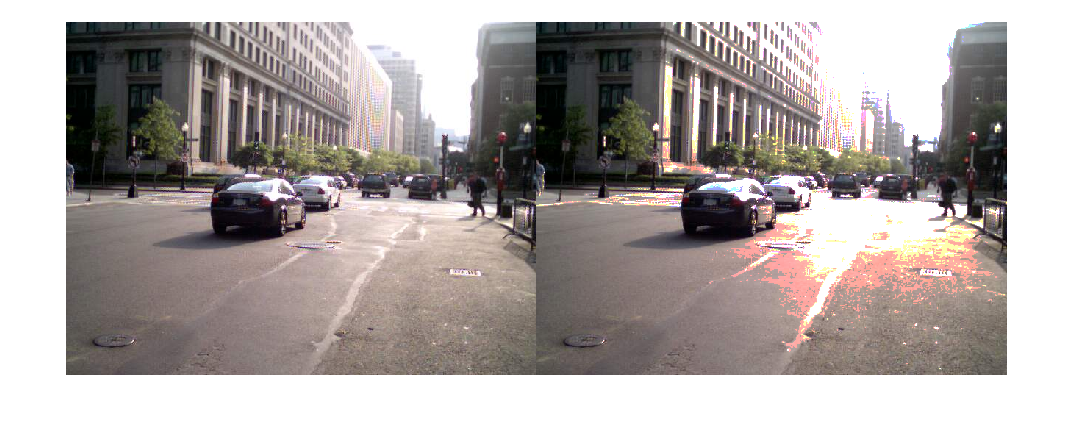

imshowpair(Streets2Input,Streets2GeminiBloom,"montage")

## Test 4: Combining the Two Bloom Functions?

Gemini's bloom brightens the pixels that meet its threshold while GPT's bloom applies a blur over the image that brightens the brighter objects, the blur from GPT's bloom might be able to hide the patchiness from Gemini's, and Gemini's could better highlight the bright objects that GPT's bloom will brighten. The final results actually seem pretty decent when tested on the lanterns image.

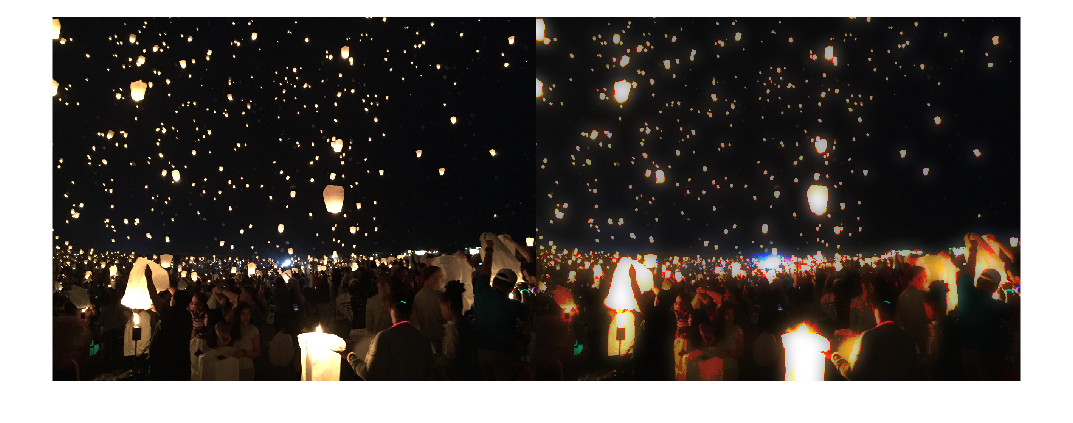

LanternGPTBloom2 = addBloom(LanternsInput,0.3,50);
LanternBloomCombined = addBloomEffect(LanternGPTBloom2,0.5,20);
imshowpair(LanternsInput,LanternBloomCombined,"montage")

function outputImage = addBloomEffect(inputImage, bloomIntensity, bloomRadius)
    % Convert the image to double for computations
    inputImage = double(inputImage) / 255.0;

    % Extract the intensity channel (you may want to adapt this for different images)
    intensity = 0.3 * inputImage(:, :, 1) + 0.59 * inputImage(:, :, 2) + 0.11 * inputImage(:, :, 3);

    % Apply a Gaussian filter to the intensity channel to create a blurred version
    blurredIntensity = imgaussfilt(intensity, bloomRadius);

    % Enhance the bright regions by adding a fraction of the blurred image to the original
    enhancedIntensity = intensity + bloomIntensity * (blurredIntensity - intensity);

    % Combine the enhanced intensity with the original color channels
    outputImage = inputImage;
    for i = 1:3
        outputImage(:, :, i) = inputImage(:, :, i) .* (enhancedIntensity ./ intensity);
    end

    % Clip values to the valid range [0, 1]
    outputImage = min(max(outputImage, 0), 1);

    % Convert back to uint8 for display
    outputImage = uint8(outputImage * 255);
end

function bloom_image = addBloom(img, strength, threshold)

% Convert image to double precision for calculations
img = double(img);

% Create blurred versions of the image with different Gaussian filters
blur1 = imgaussfilt(img, 2);
blur2 = imgaussfilt(img, 5);
blur3 = imgaussfilt(img, 10);

% Extract bright pixels exceeding the threshold
bright_pixels = (img > threshold);

% Combine blurred versions weighted by strength
bloom = (strength * blur3) + ((1 - strength) * blur2) + (0.5 * blur1);

% Apply bloom only to bright pixels
bloom = bloom .* bright_pixels;

% Add bloom to the original image
bloom_image = img + bloom;

% Convert back to uint8 range for display
bloom_image = uint8(bloom_image);

end